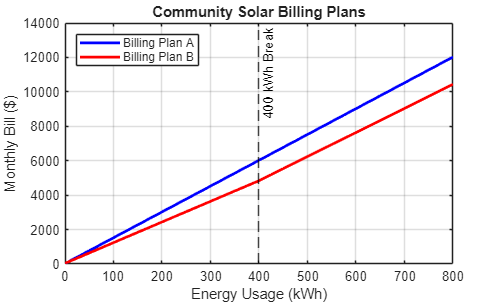

%{
Linear + Piecewise function
Author: Christopher Bourjaili
Version: 2.0
Date: 22-04-2026
Purpose:
    Showcases how costly an electric bill would be depending on usage
Input:
    - N/A:  Function is not expecting arguments.
Output:
    - Graph showcasing expected electricity bill alongside amount of
    electricity used in kWh
Engineering Algorithms:
    - Piecewise linear modeling
    - Numerical Vectorization 

What do slope and intercept represent for each plan?

The slope represents the cost per kWh (i.e. the rate of electricity cost), while the intercept represents the fixed monthly fee and 
base charge. In Plan A, the slope was 15 meaning that it represented $15 per kWh, while the intercept was 25 meaning that it 
represented $25 base fee. In Plan B, the first slope was 12 meaning that it represented the discounted rate, while the second slope 
was 14, meaning that it represented the higher rate after 400 kWh, and the intercept was 40, meaning that it represented the base fee.

How does the piecewise structure change decision-making?

The piecewise structure introduces a pricing threshold. Customers pay a lower rate up to 400 kWh, but after that usage level the price 
per kWh increases. This means customers must consider not just their total usage but whether they will exceed the threshold, which changes
the cost function.
   
 - Comparison Logic and Thresholding  
MATLAB tools/functions:
    - Vector Arithmetic
    - Array Initialization
    - Colon Operator
%}


clc 
clear
close all

x = 0:25:800;

BA = 15*x + 25;

BB = zeros(size(x));

for i = 1:length(x)
    if x(i) <= 400
        BB(i) = 12*x(i) + 40;
    else
        BB(i) = 14*x(i) - 760; 
    end
end

figure; 
plot(x, BA, 'b', 'LineWidth', 2)
hold on
plot(x, BB, 'r', 'LineWidth', 2)

xline(400, '--k', '400 kWh Break')

xlabel('Energy Usage (kWh)')
ylabel('Monthly Bill ($)')
title('Community Solar Billing Plans')
legend('Billing Plan A', 'Billing Plan B', 'Location', 'northwest');
grid on


x_intersect = (40 - 25) / (15 - 12);
y_intersect = 15*x_intersect + 25;

fprintf('Intersection point:\n');

Intersection point:


fprintf('x = %.2f kWh\n', x_intersect);

x = 5.00 kWh


fprintf('Cost = $%.2f\n\n', y_intersect);

Cost = $100.00




T = table(x', BA', BB', ...
    'VariableNames', {'Usage_kWh', 'PlanA_Bill', 'PlanB_Bill'});

disp('First 10 rows of billing table:')

First 10 rows of billing table:


disp(T(1:10,:))

    Usage_kWh    PlanA_Bill    PlanB_Bill
    _________    __________    __________

         0            25            40   
        25           400           340   
        50           775           640   
        75          1150           940   
       100          1525          1240   
       125          1900          1540   
       150          2275          1840   
       175          2650          2140   
       200          3025          2440   
       225          3400          2740   




if x_intersect <= 400
    fprintf('Recommendation:\n');
    fprintf('Plan B is cheaper for most usage levels above %.2f kWh.\n', x_intersect);
    fprintf('Plan A is only better for extremely low usage.\n');
else
    fprintf('Plans do not meaningfully intersect in the usable range.\n');
end

Recommendation:


Plan B is cheaper for most usage levels above 5.00 kWh.


Plan A is only better for extremely low usage.
